# Simple Longitudinal Vehicle Component

Copyright 2020-2021 The Mathworks, Inc.

## Open model

mdl = "Vehicle1DBasic_test_harness";
if not(bdIsLoaded(mdl))
  % A callback function in the model runs the setup script.
  open_system(mdl)
else
  Vehicle1DBasic_setup
end

## Load Input Signals

Input signals are defined as timetable object in a separate MATLAB function. This script only loads it to the workspace.

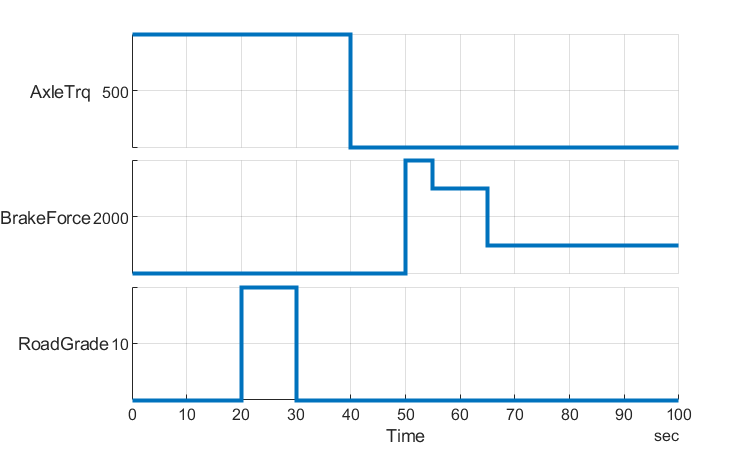

fig = figure;
[inputSignals_Vehicle1D, inputBus_Vehicle1D, t_end] = ...
  Vehicle1DBasic_inputs( "PlotParent",fig, "InputPattern","acceleration" );

## Road-Load Resisting Force

Collect the block parameters from the Vehicle 1D Basic block and plot the road-load reisisting force curve.

% Select the block
if not(bdIsLoaded(mdl)), open_system(mdl); end
target_subsystem = mdl+"/Longitudinal Vehicle";
open_system(target_subsystem)
set_param(target_subsystem+"/Longitudinal Vehicle", 'Selected', 'on')

% Collect block parameters
block_info = Vehicle1DBasic_get_block_info(gcbh)

block_info = struct with fields:
             M_e_kg: 1790
           R_tire_m: 0.3000
             A_rl_N: 175
     B_rl_N_per_kph: 0
    C_rl_N_per_kph2: 0.0320
      grav_m_per_s2: 9.8100


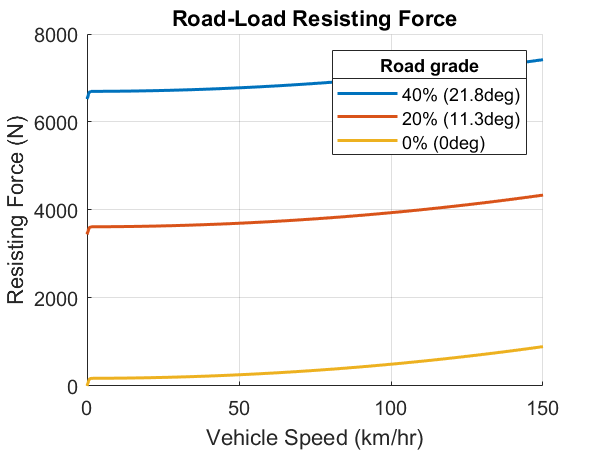


% Make a plot
Vehicle1DBasic_plot_resisting_force( ...
  "VehicleMass_kg", block_info.M_e_kg, ...
  "RoadLoadA_N", block_info.A_rl_N, ...
  "RoadLoadB_N_per_kph", block_info.B_rl_N_per_kph, ...
  "RoadLoadC_N_per_kph2", block_info.C_rl_N_per_kph2, ...
  "GravitationalAcceleration_m_per_s2", block_info.grav_m_per_s2, ...
  "VehicleSpeedVector_kph", linspace(0, 150, 200), ...
  "RoadGradeVector_pct", [40 20 0] );

## Run Simulation

Set test-specific parameters and run simulation.

% Set initial conditions
initial.vehicleSpeed_kph = 0;
initial.GeartrainSpeed_rpm = 0;

% Override block parameters

% Set Simulation Input
in = Simulink.SimulationInput(mdl);
in = in.setModelParameter('StopTime',num2str(t_end));

% Run simulation
out = sim(in);

## Visualize Simulation Result

Inpus

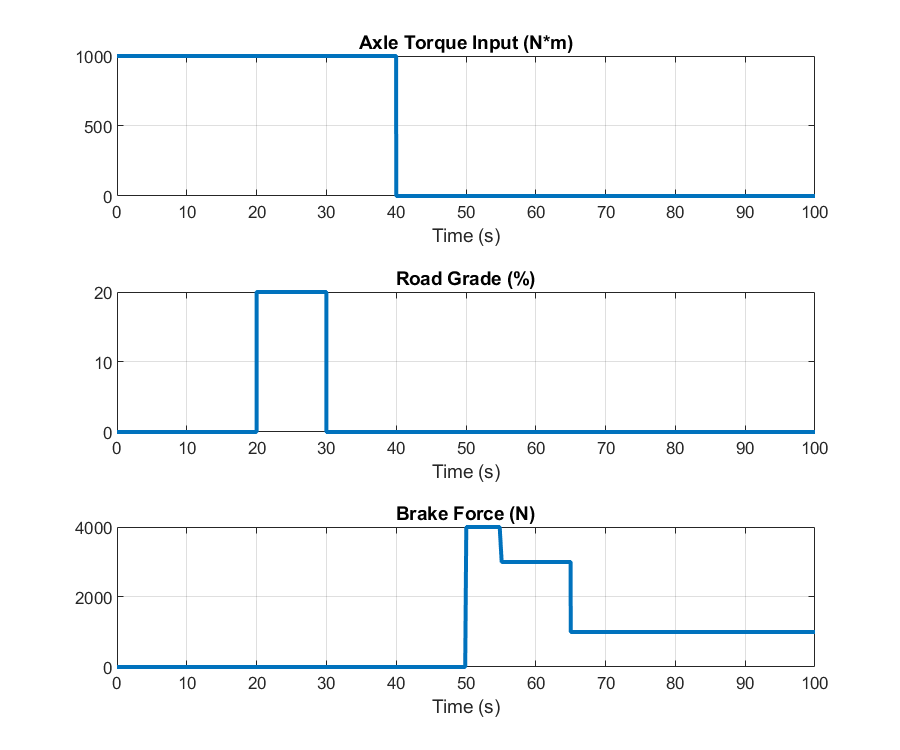

fig = figure;
Vehicle1DBasic_plot_result_inputs( "Dataset",out.logsout, "PlotParent",fig );

Outputs

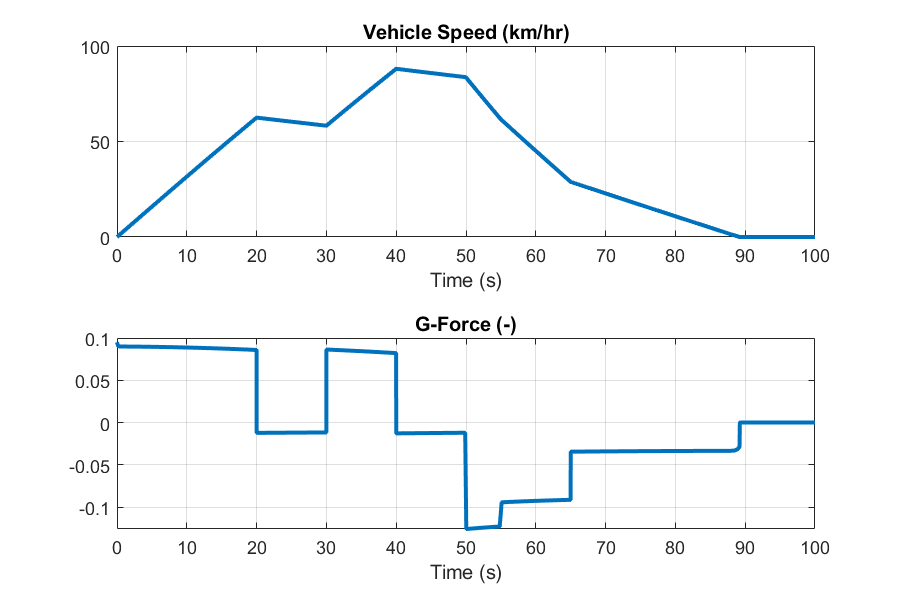

fig = figure;
Vehicle1DBasic_plot_result_outputs( "Dataset",out.logsout, "PlotParent",fig );